# Aplicaciones en ingeniería civil

## Contexto

Añadir contexto. Breve marco teórico, incluyendo fórmulas e imágenes si es necesario, sobre la aplicación que se va a desarrollar.

## Enunciado

Añadir enunciado.

## Solución

% Ingrese su código aquí :)

## Material adicional

- Añadir material adicional

***TODO LO SIGUIENTE SE PUEDE UTILIZAR PARA LA APLICACIÓN, PERO SE DEBE MEJORAR LA PRESENTACIÓN.***

# Ecuación Colebrook-White

Número de Reynolds


$$\textrm{Re}=\frac{\textrm{vD}}{\nu \;}$$


Ecuación de Colebrook y White


$$\frac{1}{\sqrt{\;f}}=-2\log_{10} \left(\frac{k/D}{3\ldotp 7}+\frac{2\ldotp 54}{\textrm{Re}\sqrt{\;f}}\right)$$


clear; clc

% Funciones anónimas.
fnc_Re = @(v, D, vc) v .* D ./ vc;
fnc_CW = @(f, k, D, Re) 1 ./ sqrt(f) + 2 .* log10(((k ./ D) / 3.7) + (2.54 ./ (Re .* sqrt(f))));

Ejemplos para la viscosidad dinámica y la viscosidad cinemática (Fuente: [Viscosidad dinámica y cinemática: definición y ejemplos (flottweg.com)](https://www.flottweg.com/es/wiki/tecnica-de-separacion/viscosidad-dinamica/)).

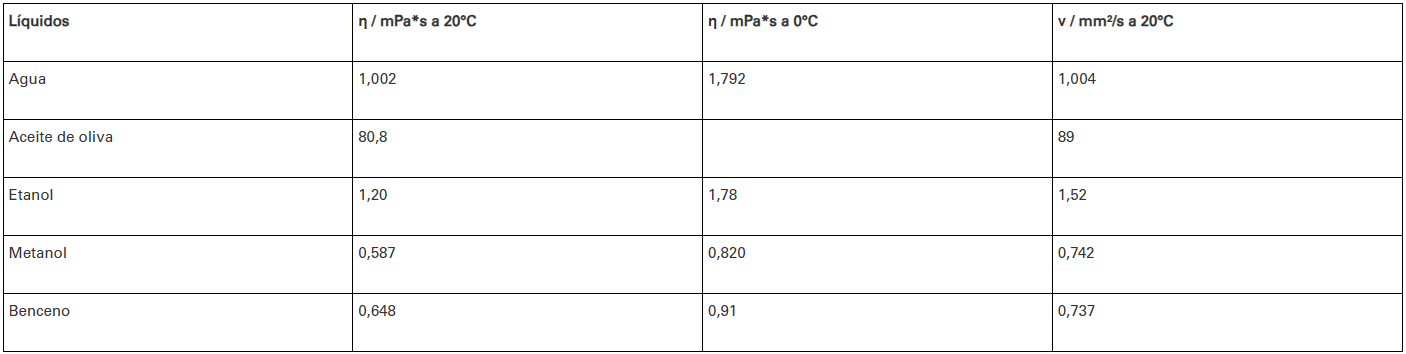

% Constantes
vc = 1.004;             % [mm^2 / s] a 20ºC
vc = vc / (1000 ^ 2);   % [m^2 / s] a 20ºC

Rugosidad absoluta (Fuente: [Rugosidad absoluta.pdf (unam.mx)](http://dicyg.fi-c.unam.mx/~lilia_unam/HIDRAULICA/MATERIAL/MATERIALCLASE/PERDIDAS/Rugosidad%20absoluta.pdf))

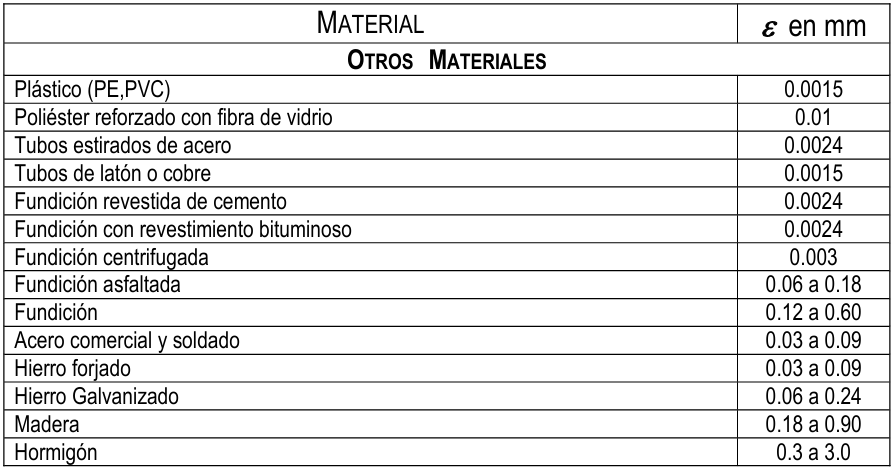

% Entradas
v = 1;                  % [m / s]
D = 50;                 % [mm]
D = D / 1000;
k = 3;                  % [mm]
k = k / 1000;           % [m]

Re = fnc_Re(v, D, vc);

if Re < 2e3
    f = 64 / Re;
else
    f0 = valor_inicial(fnc_CW, k, D, Re);
    f = fzero(@(f) fnc_CW(f, k, D, Re), f0);
end

## Funciones locales

function f0 = valor_inicial(fnc, k, D, Re)
    valores_f = linspace(.01, 1);
    [~, idx_min] = min(abs(fnc(valores_f, k, D, Re)));
    f0 = valores_f(idx_min);
end